clear
clc
load('dados_para_curvas.mat')
% Curva de vazão por sinal de controle
u = flip([10 20 30 40 50 60 70 80 90 100]);
A_T3 = pi*(31e-2)^2

A_T3 = 0.3019

h1 = [39.01 35.94 32.87 30.31 27.75 24.17 20.59 22.64 18.03 14.96]/100;
time = [60.2611 59.9732 59.8031 59.9116 59.9821 59.8828 59.8186 79.7513 80.0187 99.638];
V_T3 = A_T3*h1;
Q_T3 = V_T3./time;
plot(u,Q_T3,'.')
grid on
title('Curva de Vazão da Bomba')
xlabel('Sinal de Controle (%)');
ylabel('Vazão (m³/s)');
% Ajuste da curva
F_Qin = fit(u',Q_T3','poly1')

F_Qin =      Linear model Poly1:
     F_Qin(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    1.64e-05  (1.537e-05, 1.743e-05)
       p2 =   0.0003573  (0.0002934, 0.0004212)

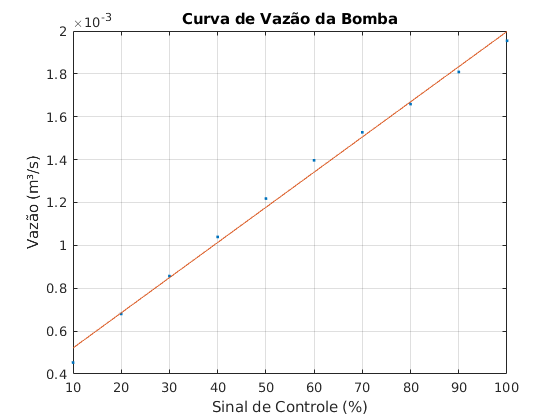

hold on
plot(u,F_Qin(u))

% Gerando uma função definida por partes
syms us
F_Qin_s = 0.00164*us + 0.003573;
F_Qin_g = piecewise(us<20,0,us>=20,F_Qin_s)

$$F\_Qin\_g = \left\{ \begin{array}{cl} 0 & \text{ if }\mathrm{us}<20\\ \frac{41\,\mathrm{us}}{25000}+\frac{514923566995033}{144115188075855872} & \text{ if }20\leq \mathrm{us} \end{array}\right.$$

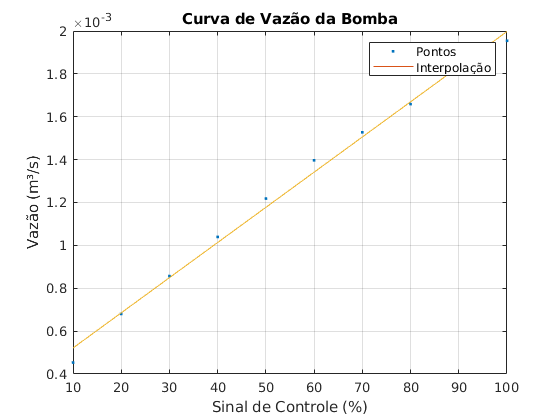


hold on
plot(u,F_Qin(u))
legend('Pontos','Interpolação')

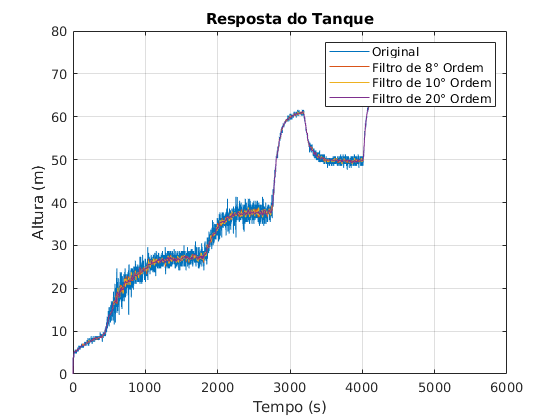

figure
Level3CM_f_8 = medfilt1(Level3CM,8);
Level3CM_f_10 = medfilt1(Level3CM,10);
Level3CM_f_20 = medfilt1(Level3CM,20);
plot(t,Level3CM);
hold on 
plot(t,Level3CM_f_8,t,Level3CM_f_10,t,Level3CM_f_20);
grid on
xlabel('Tempo (s)');
ylabel('Altura (m)')
title('Resposta do Tanque')
legend('Original','Filtro de 8° Ordem','Filtro de 10° Ordem','Filtro de 20° Ordem')

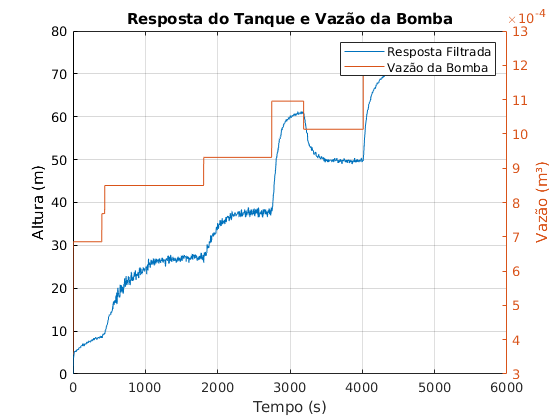

figure
plot(t,Level3CM_f_8);
yyaxis left
ylabel('Altura (m)')
hold on
yyaxis right
plot(t,F_Qin(Pump1PC))
ylabel('Vazão (m³)')
grid on
xlabel('Tempo (s)');
legend('Resposta Filtrada','Vazão da Bomba')
title('Resposta do Tanque e Vazão da Bomba')

figure
h2 = [8.392 27.11 37.48 60.93 48.98 74.91]/100;
Q_T32 = [6.854 8.494 9.315 10.96 10.13 11.78]/100;
plot(h2,Q_T32,'.')
grid on
title('Curva de Vazão da Saída')
xlabel('Altura (m)');
ylabel('Vazão (m³/s)');
% Ajuste da curva
F_Qout = fit(h2',Q_T32','poly1')

F_Qout =      Linear model Poly1:
     F_Qout(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.07398  (0.06595, 0.08201)
       p2 =      0.0641  (0.06023, 0.06797)

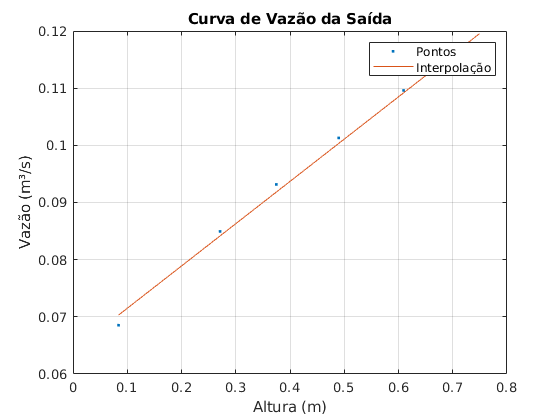

hold on
plot(h2,F_Qout(h2))
legend('Pontos','Interpolação')